This script loads in experimental data from a stored table and computes some basic summary statistics, along with simple plots

data = readtable('data_active_pos_fb.xml');

size(data)

ans =         6923           4


data.Properties.VariableNames

ans = 1×4 cell array
    {'trial'}    {'mouse'}    {'session_date'}    {'wheel_speed'}



data(1:5,:)

ans = 5×4 table
    trial    mouse     session_date    wheel_speed 
    _____    ______    ____________    ____________

      1      "Cori"    14-Dec-2016     1×250 double
      2      "Cori"    14-Dec-2016     1×250 double
      3      "Cori"    14-Dec-2016     1×250 double
      4      "Cori"    14-Dec-2016     1×250 double
      9      "Cori"    14-Dec-2016     1×250 double


mouse_names = unique(data.mouse)

mouse_names = 10×1 string array
    "Cori"
    "Forssmann"
    "Hench"
    "Lederberg"
    "Moniz"
    "Muller"
    "Radnitz"
    "Richards"
    "Tatum"
    "Theiler"



session_dates = unique(data.session_date)

session_dates = 31×1 datetime array
   14-Dec-2016
   17-Dec-2016
   18-Dec-2016
   07-Jan-2017
   08-Jan-2017
   09-Jan-2017
   10-Jan-2017
   11-Jan-2017
   12-Jan-2017
   15-May-2017
   16-May-2017
   18-May-2017
   15-Jun-2017
   16-Jun-2017
   17-Jun-2017
   18-Jun-2017
   11-Oct-2017
   29-Oct-2017
   30-Oct-2017
   31-Oct-2017
   01-Nov-2017
   02-Nov-2017
   04-Nov-2017
   05-Nov-2017
   05-Dec-2017
   06-Dec-2017
   07-Dec-2017
   08-Dec-2017
   09-Dec-2017
   10-Dec-2017


### How many trials do we have per mouse?

% Compute group summary
trials_by_mouse = groupsummary(data,"mouse")

trials_by_mouse = 10×2 table
       mouse       GroupCount
    ___________    __________

    "Cori"             451   
    "Forssmann"        718   
    "Hench"            965   
    "Lederberg"       1619   
    "Moniz"            347   
    "Muller"           522   
    "Radnitz"          637   
    "Richards"         727   
    "Tatum"            691   
    "Theiler"          246   


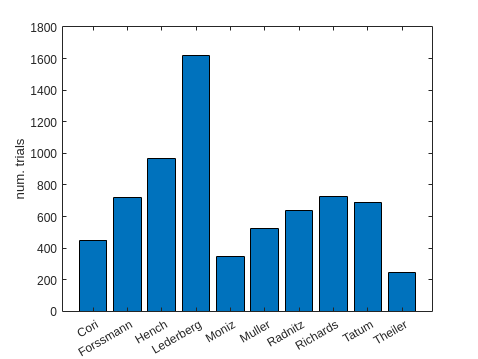

mouse_names = trials_by_mouse.mouse;
n_trials_by_mouse = trials_by_mouse.GroupCount;

bar(mouse_names,n_trials_by_mouse)
ylabel('num. trials')

### How many trials were done on each date?

Use histogram here instead of bar to get nice formatting on the x-axis

groupcounts is better than groupsummary because a normalised count (percentage) is also calculated.

unique(data.session_date) % Note Matlab autoconverted session_dates to datetime!

ans = 31×1 datetime array
   14-Dec-2016
   17-Dec-2016
   18-Dec-2016
   07-Jan-2017
   08-Jan-2017
   09-Jan-2017
   10-Jan-2017
   11-Jan-2017
   12-Jan-2017
   15-May-2017
   16-May-2017
   18-May-2017
   15-Jun-2017
   16-Jun-2017
   17-Jun-2017
   18-Jun-2017
   11-Oct-2017
   29-Oct-2017
   30-Oct-2017
   31-Oct-2017
   01-Nov-2017
   02-Nov-2017
   04-Nov-2017
   05-Nov-2017
   05-Dec-2017
   06-Dec-2017
   07-Dec-2017
   08-Dec-2017
   09-Dec-2017
   10-Dec-2017



trials_by_date = groupcounts(data,"session_date","day")

trials_by_date = 31×3 table
    day_session_date    GroupCount    Percent
    ________________    __________    _______

      14-Dec-2016          141         2.0367
      17-Dec-2016          159         2.2967
      18-Dec-2016          151         2.1811
      07-Jan-2017          311         4.4923
      08-Jan-2017          290         4.1889
      09-Jan-2017          239         3.4523
      10-Jan-2017          159         2.2967
      11-Jan-2017           85         1.2278
      12-Jan-2017           75         1.0833
      15-May-2017          142         2.0511
      16-May-2017          139         2.0078
      18-May-2017           66        0.95334
      15-Jun-2017          161         2.3256
      16-Jun-2017          255         3.6834
      17-Jun-2017          277         4.0012
      18-Jun-2017          272         3.9289


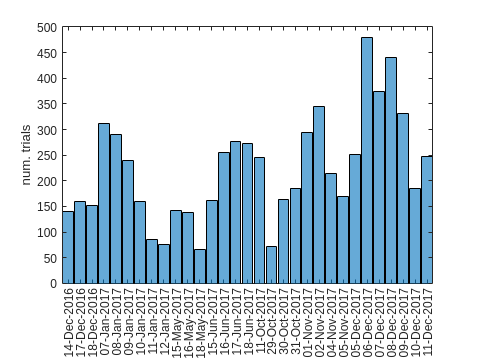


histogram('Categories', unique(trials_by_date.day_session_date ),'BinCounts', trials_by_date.GroupCount)
ylabel('num. trials')

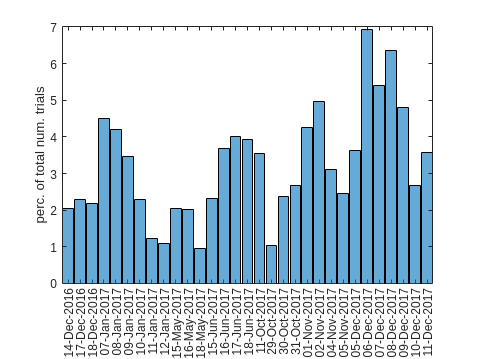


histogram('Categories', unique(trials_by_date.day_session_date ),'BinCounts', trials_by_date.Percent)
ylabel('perc. of total num. trials')

### Number of sessions each mouse was involved in

mouse_sessions=groupcounts( groupcounts(data, ["session_date","mouse"] ), "mouse")

mouse_sessions = 10×3 table
       mouse       GroupCount    Percent
    ___________    __________    _______

    "Cori"             3         7.6923 
    "Forssmann"        4         10.256 
    "Hench"            4         10.256 
    "Lederberg"        7         17.949 
    "Moniz"            3         7.6923 
    "Muller"           3         7.6923 
    "Radnitz"          5         12.821 
    "Richards"         5         12.821 
    "Tatum"            4         10.256 
    "Theiler"          1         2.5641 


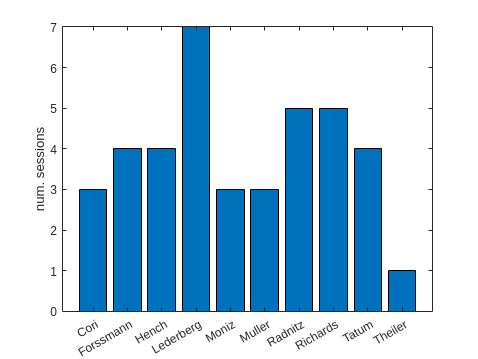


bar(mouse_sessions.mouse, mouse_sessions.GroupCount)

ylabel('num. sessions')

### More advanced grouping

Plot showing how many trials each mouse carried out on each session day

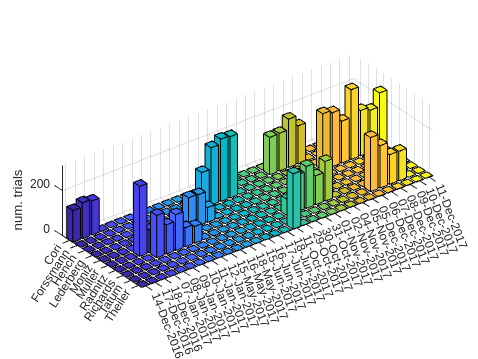

[B,BG,BP]=groupcounts({data.mouse, data.session_date}, "IncludeEmptyGroups",true);

bar3(reshape(B,length(session_dates),length(mouse_names))')
yticklabels(mouse_names)
xticks([1:1: length(session_dates)])
xticklabels( datestr(session_dates))
zlabel('num. trials')